clear;clc;close all;

R = 10;L = 0.01;C = 1e-6;
s = tf('s');
G = 1 / (L*C*s^2 + R*C*s + 1);

% 2. 设计滞后校正器
% 目标是在频率 w_c = 2000 rad/s 处，让幅值穿过 0dB。
w_c = 2000;
[mag_G, ~] = bode(G, w_c);
beta = mag_G;

z = w_c / 10;
p = z / beta;
K = 1;

C_lag = K*(s + z)/(s + p);
G_open = C_lag * G;

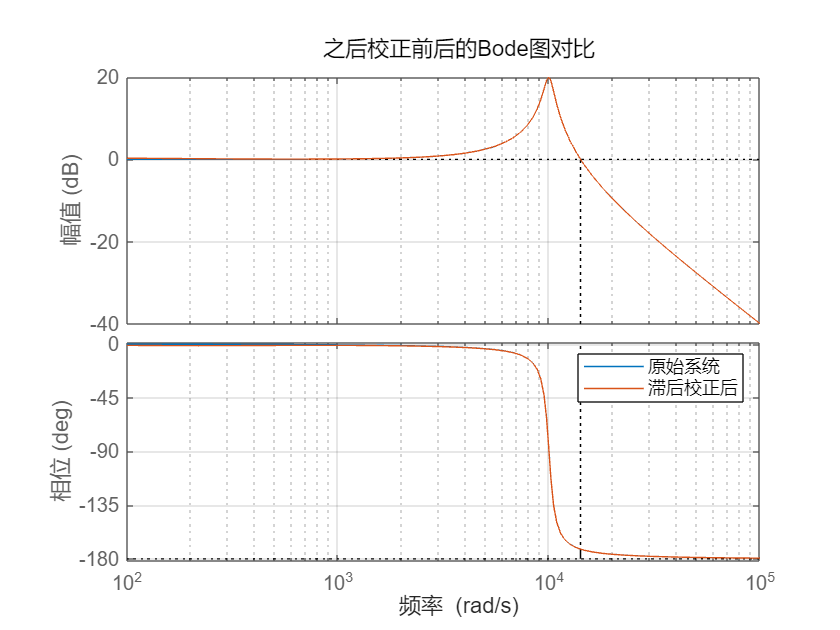

figure;
margin(G);hold on;
margin(G_open);
legend('原始系统', '滞后校正后');
title('之后校正前后的Bode图对比');
grid on;    ;

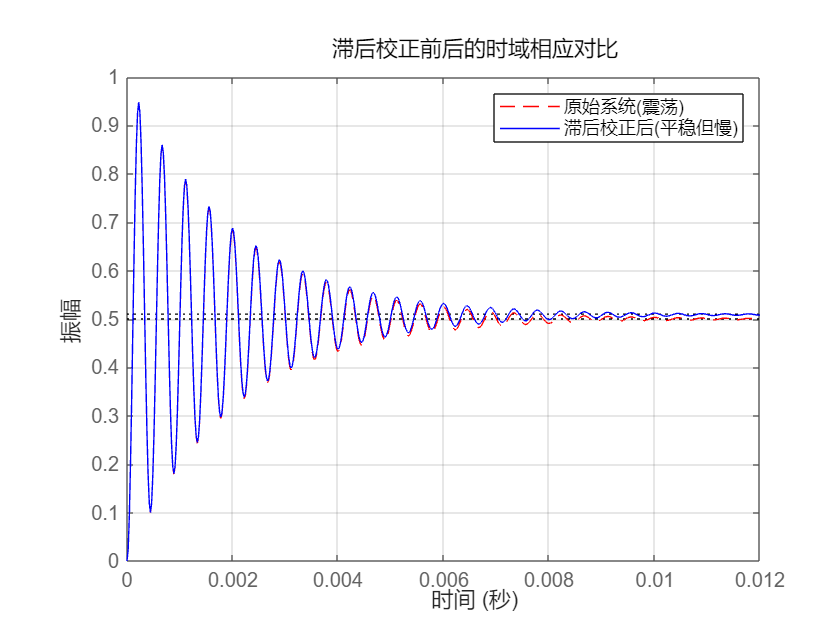


T_old = feedback(G, 1);
T_new = feedback(G_open, 1);

figure;
step(T_old, 'r--', T_new, 'b-');
legend('原始系统(震荡)', '滞后校正后(平稳但慢)');
title('滞后校正前后的时域相应对比');
grid on;